# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com / bozpoyraz20@ku.edu.tr*

## DERS - 5

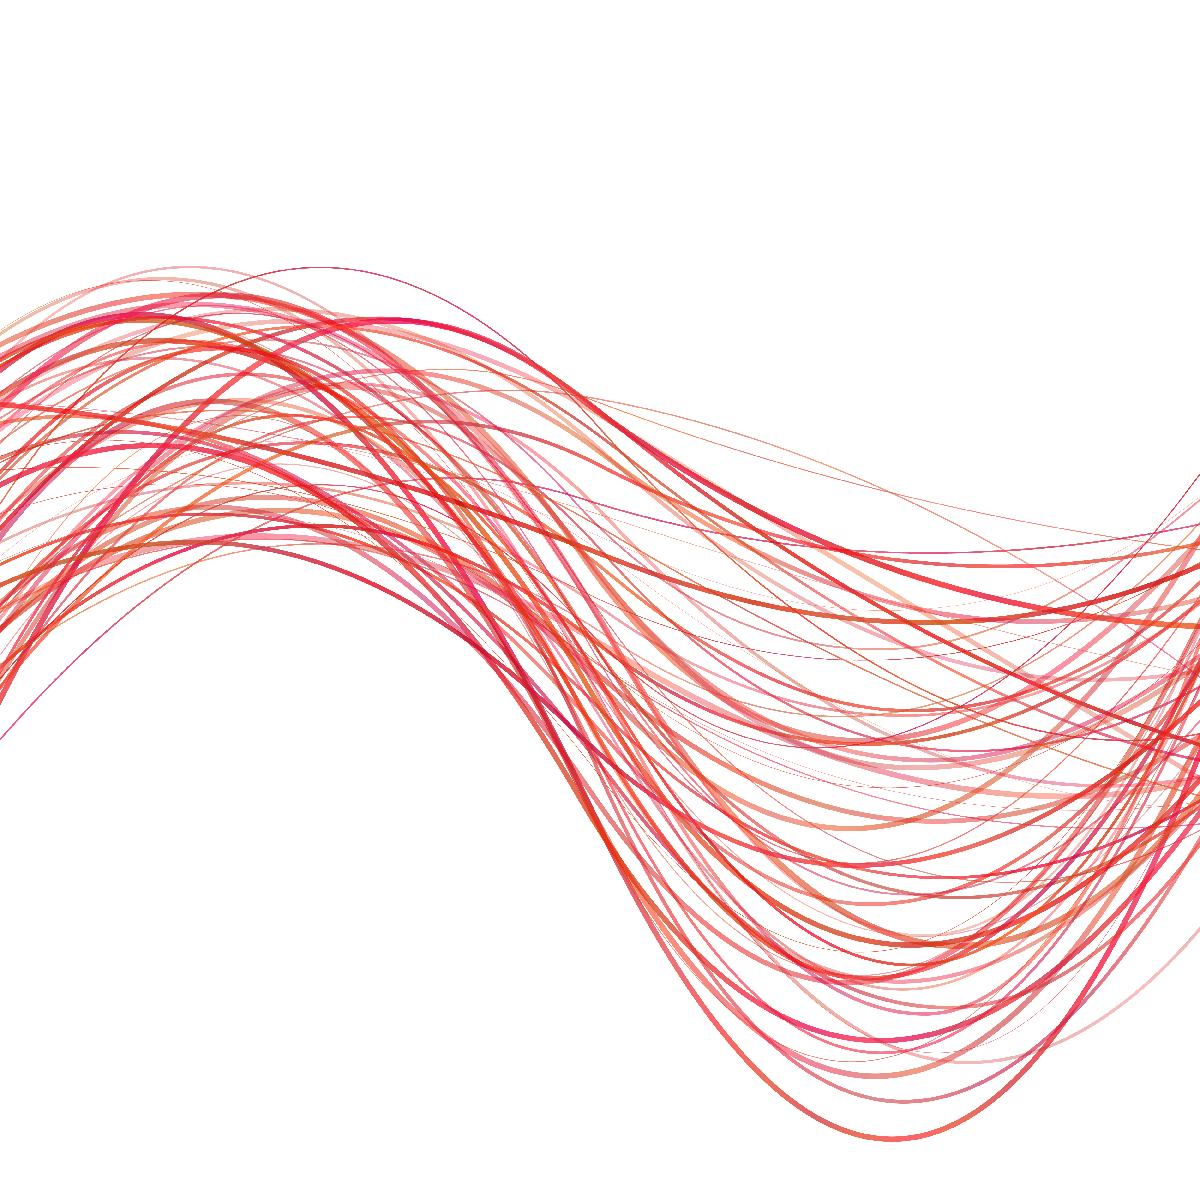

### 2-Boyutlu Grafik Çizdirme

MATLAB'de gerçekleştirilen neredeyse tüm projelerde, elde edilen sonuçları görmek için grafikler oluşturulur. Örneğin

- Matematiksel fonksiyonları,

- Rastlantı değişkenlerinin olasılık yoğunluk fonksiyonlarını,

- Bir sensörden toplanan verilerin nasıl dağıldığını,

- Herhangi bir değişkenin başka bir değişkene göre nasıl değiştiğini,

ve daha birçok merak edileni gözlemlemek için grafikler ve çizimler oldukça sık kullanılırlar. MATLAB'de grafik çizdirmek için kulanılan en temel hazır fonksiyon ***plot*** fonksiyonudur. Örneğin bir sinüs dalgasını çizdirebiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);

Grafiğin arka planını ızgara biçiminde yapmak grafiği ve verileri gözlemlemeyi kolaylaştırır. Bunun için ***grid*** hazır fonksiyonunu kullanabiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
grid;

Eksenlerin değer aralıklarını iyi ayarlamak gerekir, yoksa verileri doğru gözlemleyemeyiz. Örneğin sinüs dalgasının -1 ile 1 arasında dağıldığını biliyoruz ve eğer sinüs dalgasını -1000 ile 1000 arasındaki değerlerde incelersek sanki açıdan bağımsız olarak sabit kalan ve 0 olan bir fonksiyonmuş zannedebiliriz. Eksenlerin değiştiği değer aralıklarını farklı şekillerde ayarlayabiliriz. Bunun için ilk olarak ***axis*** hazır fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
axis([0 2 * pi -2 2]);
grid;

Eksen aralıklarını aynı zamanda ***xlim ***ve ***ylim *** fonksiyonlarını kullanarak da ayarlayabiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenleri isimlendirmek elde edilen grafiği anlamlandırmak adına oldukça önemlidir. Burada x-ekseninin hangi değişkeni temsil ettiğini göstermek için ***xlabel*** hazır fonksiyonu kullanılırken, y-ekseninin hangi değişkeni temsil ettiğini göstermek için de ***ylabel*** hazır fonksiyonu kullanılır. Grafiğe başlık koyabilmek için de ***title*** hazır fonksiyonu kullanılır. Yunan alfabesi değişken tanımlamalarında sıkça kullanıldığı için grafiklere eklemek ihtiyacı hissedebilirsiniz. Hangi harfin nasıl yazılacağı MathWorks sitesinde detaylı bir tablo olarak verilmiştir. Bunun için aşağıda verilen linki inceleyebilirsiniz:

- Yunan Alfabesi: [https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html](https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html)

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenlerde çoklu satırlar oluşturulabilir. Örneğin x-ekseninde $\theta$'nın birimini altına yazmak istersek aşağıdaki gibi gerçekleştirebiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenlerdeki yazıların boyutları, tipleri ve renkleri de isteğe göre değiştirilebilir. Bunun için de kodu aşağıdaki gibi ayarlayabiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"], "FontSize", 10, "FontWeight", "bold", "Color", "r");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

MATLAB'de bazı harfler hazır olarak bazı renkler için tanımlanmıştır:


$$\matrix{
\textbf{Color} & \textbf{Description} \cr
\text{y} & \text{Yellow} \cr
\text{m} & \text{Magenta} \cr
\text{c} & \text{Cyan} \cr
\text{r} & \text{Red} \cr
\text{g} & \text{Green} \cr
\text{b} & \text{Blue} \cr
\text{w} & \text{White} \cr
\text{k} & \text{Black}
}$$


Ancak bunlar haricinde de RGB renk kodları girerek istediğimiz rengi elde edebiliriz. Farklı renkler deneyerek grafiği tekrar oluşturalım.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "Color", [0.8500 0.3250 0.0980]);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Grafiğin kalınlığını da istediğimiz gibi ayarlayabiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 3);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Grafik sadece düz çizgi şeklinde olmak zorunda değildir, istediğimiz şekilde ayarlayabiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "v-.",...
                       "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 2);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"]);
ylabel("Fonksiyon");
xlim([1.4 1.5]);
ylim([-2 2]);
grid;

Grafiğin kalınlığını ve rengini değiştirmeden verilerin gösterildiği şekillerin kalınlığını ve rengini de değiştirebiliriz.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "o--",...
                       "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 2,...
                       "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                       "MarkerFaceColor", [0.9290 0.6940 0.1250], ...
                       "MarkerSize", 12);
title("Sinüs Dalgası");
xlabel(["\theta","(rad)"]);
ylabel("Fonksiyon");
xlim([1.4 1.5]);
ylim([-2 2]);
grid;

Birden fazla veriyi aynı grafik üzerinde gözlemleyebiliriz. Bunun için*** hold on ***hazır fonksiyonunu kullanabiliriz. Tüm çizim kodları tamamlandıktan sonra da ***hold off *** fonksiyonu ile çizimin bittiğini bildirmeliyiz ki sonraki çizimler de bu grafik üzerinde çıkmasın. Örneğin bir sinüs ve bir kosinüs dalgasını aynı grafik üzerinde gösterelim.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

plot(theta, sine_wave);
hold on;
plot(theta, cos_wave);
hold off;

title("Sinüs ve Kosinüs Dalgaları");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Birden fazla veri aynı grafik üzerinde gösterilirken karışıklık olmaması açısından verileri tanımlamak gerekir. Bunun için de ***legend ***hazır fonksiyonu kullanılır.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

plot(theta, sine_wave);
hold on;
plot(theta, cos_wave);
hold off;

title("Sinüs ve Kosinüs Dalgaları");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
legend("Sinüs","Kosinüs");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Bir grafikte bir veri göstermek istiyorsak, ancak birden fazla veriyi de aynı anda gözlemlemek istiyorsak o zaman alt grafikler oluşturabiliriz. Bunun için ***subplot ***fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

x = -10 : 10;
square_x = x.^2;
cube_x = x.^3;

subplot(2, 2, 1);
plot(theta, sine_wave, "LineWidth", 2,...
                       "Color", [0.9290 0.6940 0.1250]);
title("Sinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;
hold off;

subplot(2, 2, 2);
plot(theta, cos_wave, "LineWidth", 2,...
                      "Color", [0 0.4470 0.7410]);
title("Kosinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;
hold off;

subplot(2, 2, 3);
plot(x, square_x, "--",...  
                  "LineWidth", 2,...
                  "Color", [0.4660 0.6740 0.1880]);
title("x^{2}");
xlabel("x");
ylabel("Fonksiyon");
grid;
hold off;

subplot(2, 2, 4);
plot(x, cube_x, "-.",...  
                "LineWidth", 2,...
                "Color", [0.4940 0.1840 0.5560]);
title("x^{3}");
xlabel("x");
ylabel("Fonksiyon");
grid;
hold off;

-----------------------------------------------------------------

**ÖRNEK**

Aşağıda verilen fonksiyonu ve ilk beş dereceden türevlerini bir döngü yardımıyla çizdiriniz. Çizdirirken aşağıdaki kurallara dikkat ediniz:

- Fonksiyonun kendisini ve çift dereceden türevlerini [0.6350 0.0780 0.1840] renk kodu ile çizdirirken tek dereceden türevleri [0.9290 0.6940 0.1250] renk kodu ile çizdiriniz.

- Fonksiyonun kendisinden en yüksek dereceli türeve doğru sırasıyla "-", "--", ":", "-.", "-", "--" çizgi stillerini kullanarak çizdiriniz.

- Türevlerin beklenen değerlerini de birinci dereceden en yüksek dereceye doğru sırasıyla "d", "o", "s", "v", ">" işaretleri ile çizdiriniz ve hesaplanan türevler ile üst üste çıktığından emin olunuz.

- Lejant ekleyerek hangi grafiğin hangi fonksiyona ait olduğunu belirtiniz.


$$f(x) = x^{5} + 8x^{4} - x^{3} + 5e^{2x} + 12x - 9$$


x = -0.5 : 0.01 : 0.5;
f = x.^5 + 8 * x.^4 - x.^3 + 5 * exp(2 * x) + 12 * x - 9;

line_style_array = ["--",":","-.","-","--"];

figure;
plot(x, f, "-", "Color", [0.6350 0.0780 0.1840]);
hold on;
for n = 1 : 5
    f = diff(f) ./ diff(x);
    x = x(2 : end);
    if mod(n, 2) == 0
        plot(x, f, "Color", [0.6350 0.0780 0.1840],...
                   "LineStyle", line_style_array(n));
    else
        plot(x, f, "Color", [0.9290 0.6940 0.1250],...
                   "LineStyle", line_style_array(n));
    end
    hold on;
end

x = -0.5 : 0.01 : 0.5;
x1 = x(2 : end);
f1 = 5 * x1.^4 + 32 * x1.^3 - 3 * x1.^2 + 10 * exp(2 * x1) + 12;

x2 = x1(2 : end);
f2 = 20 * x2.^3 + 96 * x2.^2  - 6 * x2 + 20 * exp(2 * x2);

x3 = x2(2 : end);
f3 = 60 * x3.^2 + 192 * x3 - 6 + 40 * exp(2 * x3);

x4 = x3(2 : end);
f4 = 120 * x4 + 192 + 80 * exp(2 * x4);

x5 = x4(2 : end);
f5 = 120 + 160 * exp(2 * x5);

plot(x1, f1, "d", "Color", [0.9290 0.6940 0.1250]);
hold on;
plot(x2, f2, "o", "Color", [0.6350 0.0780 0.1840]);
hold on;
plot(x3, f3, "s", "Color", [0.9290 0.6940 0.1250]);
hold on;
plot(x4, f4, "v", "Color", [0.6350 0.0780 0.1840]);
hold on;
plot(x5, f5, ">", "Color", [0.9290 0.6940 0.1250]);
hold off;

xlabel("x");
ylabel("y");
legend("f", "1. Derivative",...
    "2. Derivative",...
    "3. Derivative",...
    "4. Derivative",...
    "5. Derivative");
xlim([-0.005 0.005]);
grid;

-----------------------------------------------------------------

Plot komutuna alternatif olarak başka çizdirme fonksiyonları da vardır. Eğer y-ekseni logaritmik olarak çizdirilmek istenirse ***semilogy ***fonksiyonu kullanılabilir.

figure;
theta = 0 : 0.01 : 2 * pi;
f = exp(10 * cos(0.1 * theta));

subplot(2, 1, 1);
plot(theta, f);
grid;

subplot(2, 1, 2);
semilogy(theta, f);
grid;

Ayrık fonksiyonları göstermek için ***stem ***komutu kullanılabilir.

figure;
daily_temperatures = [-1 4 5 6 5 2];
days = [1 2 3 4 5 6];
stem(days, daily_temperatures);
xlabel("Days");
ylabel("Temperature");
grid;

Histogram çizdirmek için ***bar*** komutu kullanılabilir.

figure;
x = -2.9 : 0.2 : 2.9;
bar(x, exp(-x .* x));

### 3-Boyutlu Grafik Çizdirme

İki değişkene bağlı olan fonksiyonların grafiklerini incelemek ve bazı üç boyutlu modellemeleri gerçekleştirmek için üç boyutlu çizim yapmamız gerekmektedir. Bu çizimleri yapmadan önce kullanmamız gereken anahtar komut ***meshgrid ***komutudur. Bu komut sonucunda iki adet matris oluşturur: Satırlarında her $x$ (birinci değişken) değerleri olan bir matris ve her sütununda $y$ (ikinci değişken) değerleri olan bir matris. Sonra bu matrisler kullanılarak $x$ ve $y$ değişkenlerine bağlı olan fonksiyon ***surf*** komutu ile çizdirilir. Örneğin $f(x,y) = xe^{-x^{2}-y^{2}}$ fonksiyonunu $x \in [-2, 2]$ ve $y \in [-2, 2]$ aralıkları için üç boyutlu olarak çizdirelim.

x = -2 : 0.15 : 2;
y = -2 : 0.15 : 2;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

Üç boyutlu çizim haritadaki farklı değerler için farklı renkler almaktadır. Bu renk skalası ***colormap*** komutu kullanılarak değiştirilebilir.

x = -2 : 0.15 : 2;
y = -2 : 0.15 : 2;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
colormap(prism);
xlabel("x");
ylabel("y");
zlabel("z");

Benzer bir biçimde ***mesh ***komutu kullanılarak da aynı grafik yüzeyler boş kalacak şekilde elde edilebilir.

x = -2 : 0.15 : 2;
y = -2 : 0.15 : 2;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
mesh(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

Son olarak da izohips benzeri bir grafik elde edebilmek için ***contour*** komutu kullanılabilir.

x = -2 : 0.15 : 2;
y = -2 : 0.15 : 2;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
contour(X, Y, Z, 10);
xlabel("x");
ylabel("y");
zlabel("z");

Eğer hem üç boyutlu grafiği hem de izdüşümünü görmek istiyorsanız ***surfc*** komutu kullanılabilir.

x = -2 : 0.15 : 2;
y = -2 : 0.15 : 2;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surfc(X, Y, Z);
colormap(lines)
xlabel("x");
ylabel("y");
zlabel("z");